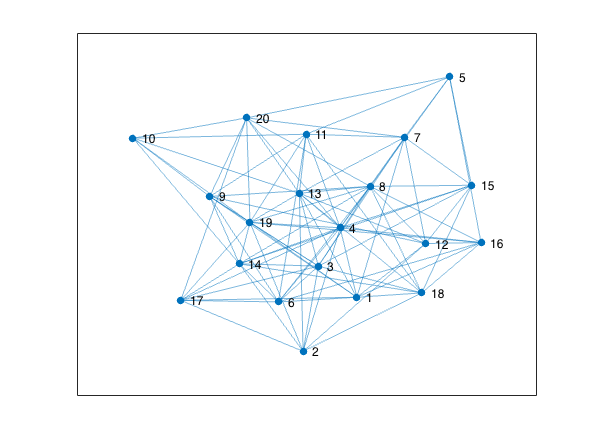

N=20;

% https://uk.mathworks.com/matlabcentral/answers/312551-generating-a-random-symmetric-matrix
% Generating a random symmetric matrix
% Alexandra Harkai on 16 Nov 2016
% Creates random connected undirected adjacency matrix
A = randi(2,N,N)-1 ;
A = A - tril(A,-1) + triu(A,1)';

% graph omits self loops
G = graph(A, 'omitSelfLoops');
plot(G)

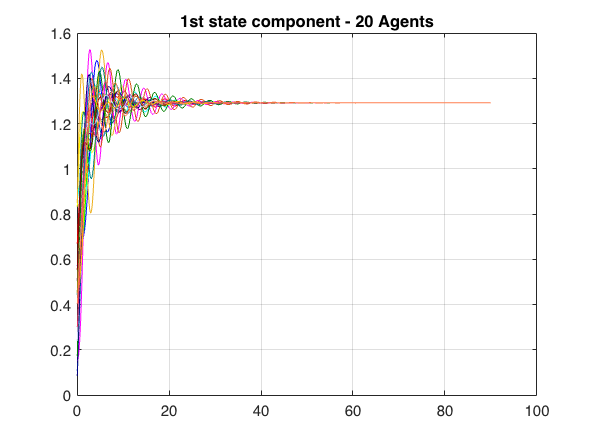


% Laplacian matrix of graph(G)
L = laplacian(G);

%Agent initial position (random)
x0=rand(3*N,1);

%% system

I=eye(N);
Y=I;
%E1=[ 0 1 0; 0 0 1; 0 -2 -3];
E2=[ 0 1 0; 0 0 1; 0 -4 -6];
F=[ 0 0 0; 0 0 0; 1 0 0 ];
 
O=(kron(I,E2))-(kron((Y*L),F));
V=ones(3*N,1);
W=eye(3*N);
X=0;
sys=ss(O,V,W,X);

t = 0:0.01:90;
%u = max(0,min(t-1,1));
u=zeros(size(t));
 
[y,t,x]=lsim(sys, u, t, x0);

%% plot
figure;
plot(t,y(:,1),'r'); %red
hold on
plot(t,y(:,4),'b'); %blue
plot(t,y(:,7),'g'); %green
plot(t,y(:,10),'m'); %magenta
plot(t,y(:,13),'y'); %yellow
plot(t,y(:,16),'c'); %cyan
plot(t,y(:,19),'color','#0072BD'); %curtain blue
plot(t,y(:,22),'color','#D95319'); %burnt orange
plot(t,y(:,25),'color','#EDB120'); %mustard
plot(t,y(:,28),'color','#7E2F8E'); %lime
plot(t,y(:,31),'color','#800080'); %purple
plot(t,y(:,34),'color','#000080'); %navy
plot(t,y(:,37),'color','#008000'); %green
plot(t,y(:,40),'color','#008080'); %teal
plot(t,y(:,43),'color','#808000'); %olive
plot(t,y(:,46),'color','#800000'); %maroon
plot(t,y(:,49),'color','#CCCCFF'); %pastel purple
plot(t,y(:,52),'color','#FFBF00'); %pastel orange
plot(t,y(:,55),'color','#DE3163'); %pastel pink
plot(t,y(:,58),'color','#FF7F50'); %pastel burnt orange
grid on
title('1st state component - 20 Agents')
hold off

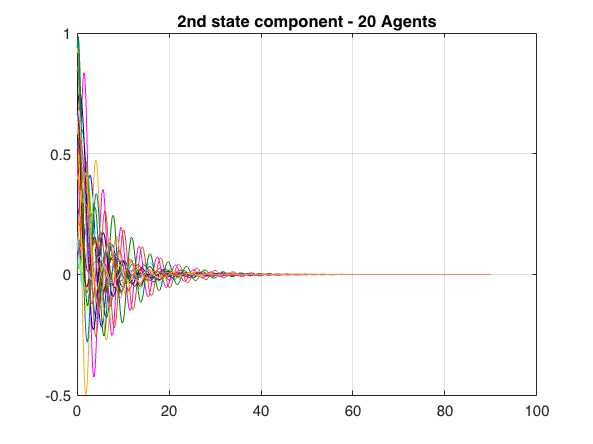

 
figure;
plot(t,y(:,2),'r');
hold on
plot(t,y(:,5),'b');
plot(t,y(:,8),'g');
plot(t,y(:,11),'m');
plot(t,y(:,14),'y');
plot(t,y(:,17),'c');
plot(t,y(:,20),'color','#0072BD');
plot(t,y(:,23),'color','#D95319');
plot(t,y(:,26),'color','#EDB120');
plot(t,y(:,29),'color','#7E2F8E');
plot(t,y(:,32),'color','#800080'); %purple
plot(t,y(:,35),'color','#000080'); %navy
plot(t,y(:,38),'color','#008000'); %green
plot(t,y(:,41),'color','#008080'); %teal
plot(t,y(:,44),'color','#808000'); %olive
plot(t,y(:,47),'color','#800000'); %maroon
plot(t,y(:,50),'color','#CCCCFF'); %pastel purple
plot(t,y(:,53),'color','#FFBF00'); %pastel orange
plot(t,y(:,56),'color','#DE3163'); %pastel pink
plot(t,y(:,59),'color','#FF7F50'); %pastel burnt orange
grid on
title('2nd state component - 20 Agents')
hold off

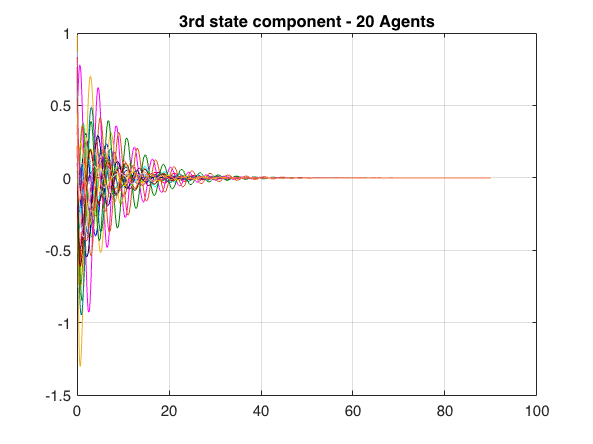

 
figure;
plot(t,y(:,3),'r');
hold on
plot(t,y(:,6),'b');
plot(t,y(:,9),'g');
plot(t,y(:,12),'m');
plot(t,y(:,15),'y');
plot(t,y(:,18),'c');
plot(t,y(:,21),'color','#0072BD');
plot(t,y(:,24),'color','#D95319');
plot(t,y(:,27),'color','#EDB120');
plot(t,y(:,30),'color','#7E2F8E');
plot(t,y(:,33),'color','#800080'); %purple
plot(t,y(:,36),'color','#000080'); %navy
plot(t,y(:,39),'color','#008000'); %green
plot(t,y(:,42),'color','#008080'); %teal
plot(t,y(:,45),'color','#808000'); %olive
plot(t,y(:,48),'color','#800000'); %maroon
plot(t,y(:,51),'color','#CCCCFF'); %pastel purple
plot(t,y(:,54),'color','#FFBF00'); %pastel orange
plot(t,y(:,57),'color','#DE3163'); %pastel hot pink
plot(t,y(:,60),'color','#FF7F50'); %pastel burnt orange
grid on
title('3rd state component - 20 Agents')
hold off